# Run the optimisation.


Lethality = [0.00022274,0.00022274,0.00022274,0.00022274,0.00022274,0.00221398,0.01351613,0.134212];
P = lib.classes.OptProblem(...
    'CostFunc', 'total_deaths', ...
    'CostFuncParams', Lethality, ...
    'VaccineEfficacy', 0.9, ...
    'MaxVaccinesPerDay', 1e5, ...
    'ReprNum', 1.5, ...
    'Steps', 300 ...
);

## Normal situation.

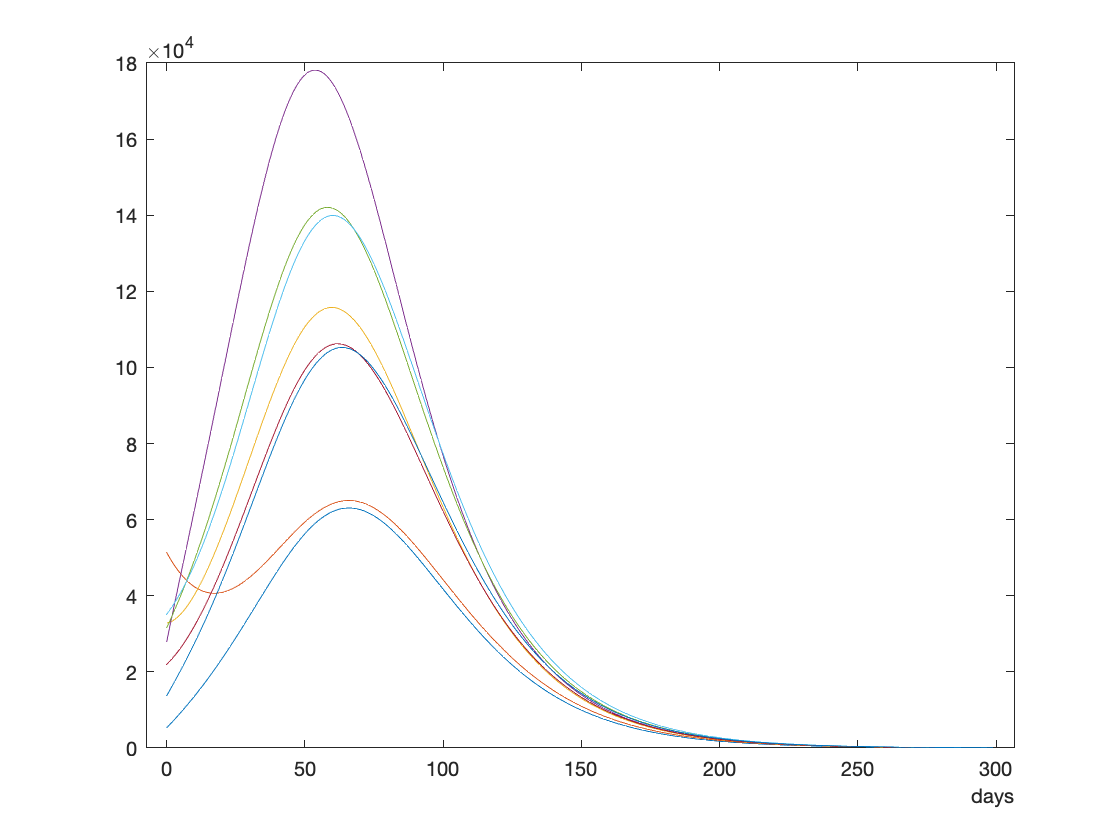

NMR = P.getResult();
figure;
plot(NMR.T, NMR.I');

## Genetic Algoritm.

[ga_VS, ga_score] = P.runGeneticAlgorithm( ...
    'MaxGenerations', 5000, ...
    'MaxStallGenerations', 4000, ...
    'InitBestOrderStrategies', 40, ...
    'InitRandomOrderStrategies', 160, ...
    'InitRandomFullStrategies', 200 ...
);

-> Creating the optimisation problem parameters...
  -> Creating the optimisation problem options...
    -> Creating the population matrix...
      -> Creating 40 best order strategies...
        -> Getting all permutations of 8 groups...
        -> Getting all 40320 order strategies...
        -> Compute the scores of the 40320 order strategies...
        -> Order the 40320 order strategies by their score...
      -> Creating 160 random order strategies...
      -> Creating 200 random full strategies...
[X]___ Optimisation options have been created!___________________________________
  ga options:

   Set properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @OptProblem.get.CreationFcn/f
                    CrossoverFcn: {@crossoverintermediate  [1]}
                         Display: 'final'
                      EliteCount: 20
                    FitnessLimit: 0
         

Optimization terminated: stop requested from plot function.


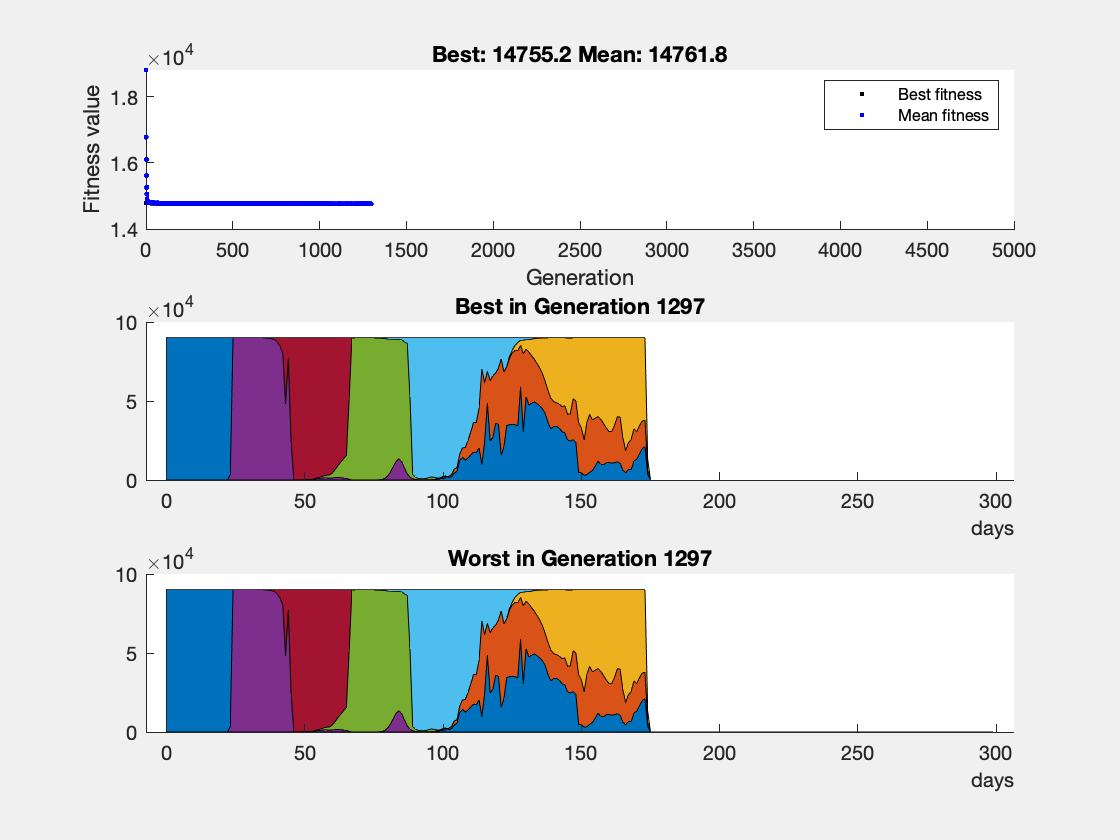

ans =   1×8 Area array:

    Area    Area    Area    Area    Area    Area    Area    Area


ga_VS.plotArea()

ga_score

ga_score = 1.4755e+04

## Differential Evolution.

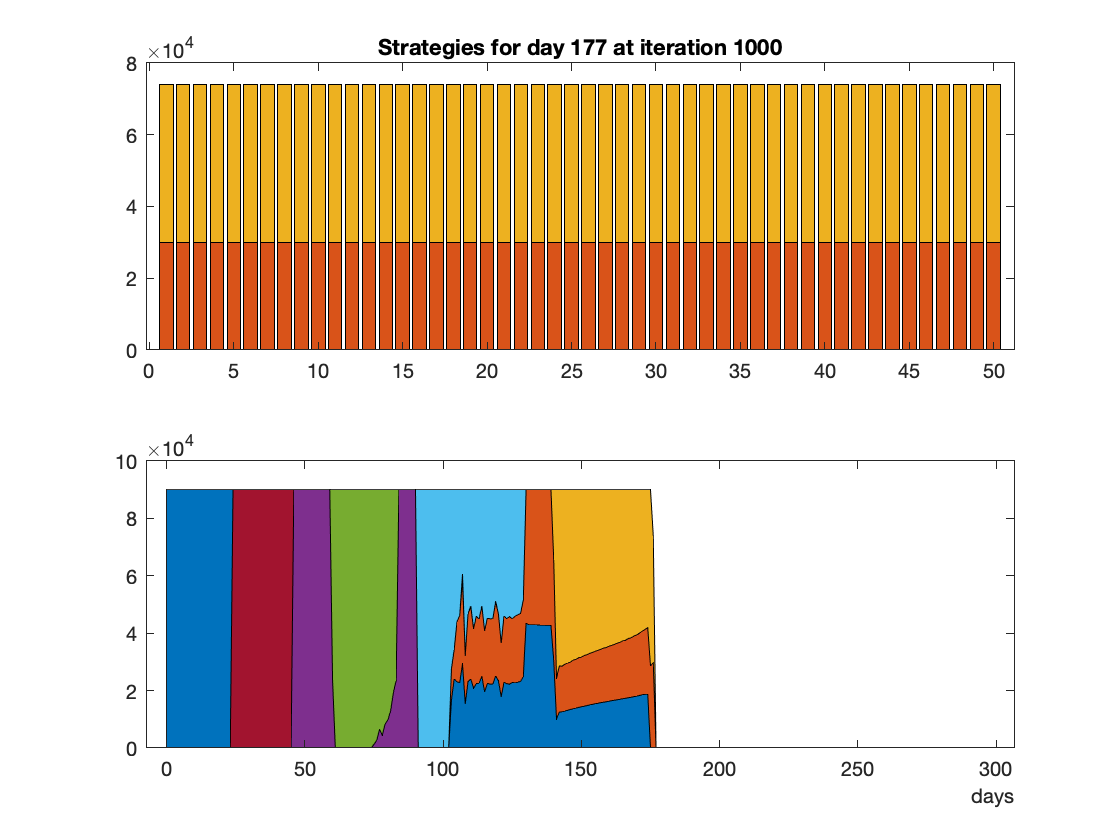

ans =   1×8 Area array:

    Area    Area    Area    Area    Area    Area    Area    Area


[de_VS, de_score] = P.runDifferentialEvolution( ...
    'Iterations', 1000 , ...
    'PopulationSize', 50 ...
);
de_VS.plotArea()

de_score

de_score = 1.5089e+04